close all; clear variables; clc;

## Laplace transform

f = 1e3 : 10e3 : 1e9;
s = 1j .* f .* 2 .* pi;

% Integrated range of RMS jitter 
Nstart = 1;
Nstop = 10001; % 100MHz
% Nstop = 1001; % 10MHz
% Nstop = 4001; % 40MHz
% Nstop = length(f); % 1GHz
Q = 10;
y = 1;
%Constants
k = 1.38e-23;
T = 300;
Fref = 50e6;

J = 10:0.1:500;


Flim = Fref/10;
n_psd_ref = 1e-16;
Sref = 1e-16;

JREF2 = 0.1 .*Sref ./(4.*pi.*Fref);

P1 = k .*T.*(1+y) .* Sref./((pi.^2) .* (Q.^2) .* (Fref.^2) .* ((J.*1e-15).^4));
P2 =  k .*T.*(1+y) ./((pi) .* (Q.^2) .* (Flim) .* ((J.*1e-15).^2 - JREF2));

for i = 1:1:4901
    if i < 1693
        P(i) = P1(i);
    else P(i) = P2(i);
    end
end

figure(1)
loglog(J,P1.*1e3,J,P2.*1e3,J,P.*1e3,'LineWidth',2);
set(gca, 'FontName', 'Arial', 'fontsize', 12, 'fontweight', 'b');
axis ([10 500 0.1 1000]);

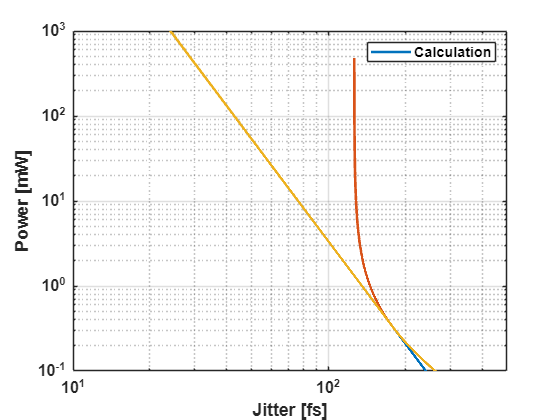

grid on;
legend ('Calculation');
xlabel('Jitter [fs]');
ylabel('Power [mW]');